Planteamiento del movimiento del robot 

Plantemiento a partir de la pose del robot

% valor de las entradas

x_O_P_in = 0.3; %m
y_O_P_in = 0.3; %m
theta_O_P_in= 0.0; %rad

x_O_P_fin = 0.3;%m
y_O_P_fin = -0.3;%m
theta_O_P_fin= 0.0; %rad

tf = 10; % seg tiempo de ejecucion de la tarea

%Poses
xi_in = [x_O_P_in;y_O_P_in;theta_O_P_in]; % pose inicial

xi_fin = [x_O_P_fin;y_O_P_fin;theta_O_P_fin]; % pose final

t= 0;

for i=1:tf+1

    x_tray(i) = x_O_P_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + ...
        (6/tf^5)*t^5) * (x_O_P_fin - x_O_P_in);

    y_tray(i) = y_O_P_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + ...
        (6/tf^5)*t^5) * (y_O_P_fin - y_O_P_in);

    theta_tray(i) = theta_O_P_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + ...
        (6/tf^5)*t^5) * (theta_O_P_fin - theta_O_P_in);
    t=t+1;
end


Calculo de las posturas del robot

% longitud de los eslabones

L1 = 0.6; %m
L2 = 0.6; %m
L3 = 0.2; %m

% Solucion geometrica de la trayectoria

for i=1:tf+1
    
    % Calculo del desacoplamiento
    x3 = x_tray(i)-L3*cos(theta_tray(i));
    y3 = y_tray(i)-L3*sin(theta_tray(i));

    % Calculo de theta_2 y theta_1
  
    theta_2_tray(i)= acos((x3^2 + y3^2 - L1^2 - L2^2)/(2*L1*L2));

    epsilon = atan2(y3,x3);
    alpha = acos((x3^2+y3^2+L1^2-L2^2)/(2*L1*sqrt(x3^2+y3^2)));

    theta_1_tray(i) = epsilon - alpha;

    theta_3_tray(i) = theta_tray(i) - theta_1_tray(i) - theta_2_tray(i);

    w(i) = abs((L1*L2*sin(theta_2_tray(i)))/(L1*L2));

    t_sim(i) = i;

end

Comprobación mediante la manipulabilidad

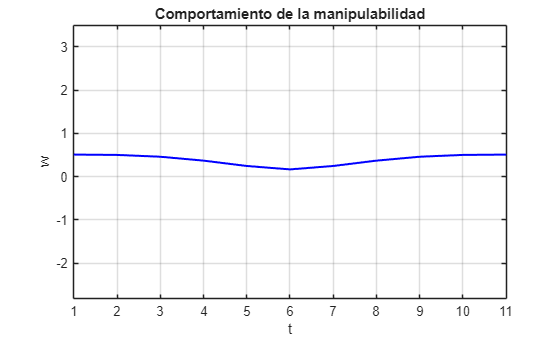




% Graficar la trayectoria cartesiana y las variables articulares
figure;
plot( t_sim, w, 'b-', 'LineWidth', 1.5);
axis equal; grid on;
xlabel('t'); ylabel('w');
title('Comportamiento de la manipulabilidad');

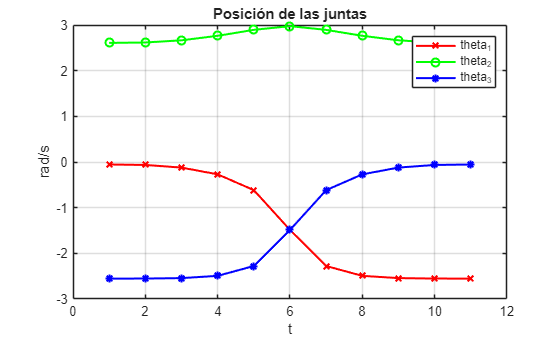

figure
plot(t_sim, theta_1_tray, 'r-x', 'LineWidth', 1.5);
hold on;
plot(t_sim, theta_2_tray, 'g-o', 'LineWidth', 1.5);
plot(t_sim, theta_3_tray, 'b-*', 'LineWidth', 1.5);
grid on;
xlabel('t'); ylabel('rad/s');
legend('theta_1', 'theta_2', 'theta_3');
title('Posición de las juntas');

Análsis de un robot Scara en el espacio de las juntas

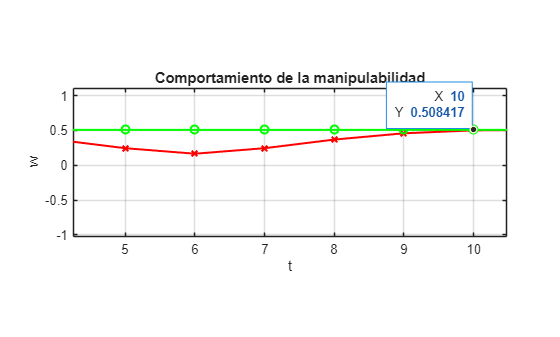

% Condiciones iniciales
theta_1_q_in = theta_1_tray(1);
theta_2_q_in = theta_2_tray(1);
theta_3_q_in = theta_3_tray(1);

% Condiciones finales

theta_1_q_fin = theta_1_tray(11);
theta_2_q_fin = theta_2_tray(11);
theta_3_q_fin = theta_3_tray(11);
t =0;
for i=1:tf+1

    theta_1_q(i) = theta_1_q_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5) * (theta_1_q_fin - theta_1_q_in);
    
    theta_2_q(i) = theta_2_q_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + ...
        (6/tf^5)*t^5) * (theta_2_q_fin - theta_2_q_in);

    theta_3_q(i) = theta_1_q_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + ...
        (6/tf^5)*t^5) * (theta_3_q_fin - theta_3_q_in);

    w_q(i) = abs((L1*L2*sin(theta_2_q(i)))/(L1*L2));

    t = t+1;
end

% Graficar la trayectoria cartesiana y las variables articulares
figure;
plot( t_sim, w, 'r-x', 'LineWidth', 1.5);
hold on;
plot( t_sim, w_q, 'g-o', 'LineWidth', 1.5);
axis equal; grid on;
xlabel('t'); ylabel('w');
title('Comportamiento de la manipulabilidad');

xlim([4.25 10.48])
ylim([-1.02 1.1])
 
ax = gca;
chart = ax.Children(1);
datatip(chart,10,0.2751);

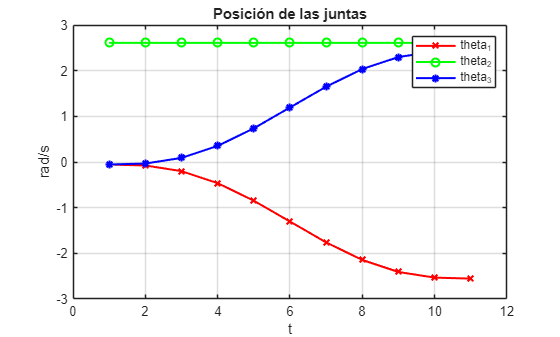

figure
plot(t_sim, theta_1_q, 'r-x', 'LineWidth', 1.5);
hold on;
plot(t_sim, theta_2_q, 'g-o', 'LineWidth', 1.5);
plot(t_sim, theta_3_q, 'b-*', 'LineWidth', 1.5);
grid on;
xlabel('t'); ylabel('rad/s');
legend('theta_1', 'theta_2', 'theta_3');
title('Posición de las juntas');

Análsis cinemático 

Cinemáica inversa de la trayectoria

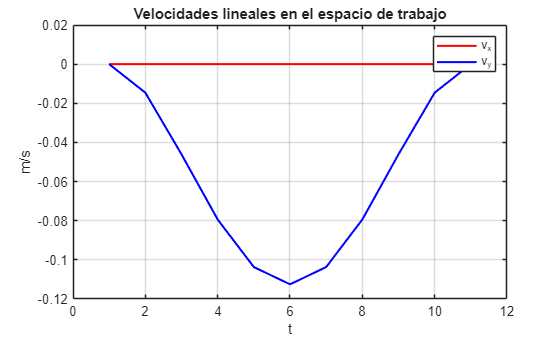

% Calculo de las velocidades en el espacio de trabajo

t=0;
for i=1:tf+1
    t = i-1; % Increment time for the next iteration
    x_tray_v(i) =  ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(x_O_P_fin - x_O_P_in);
    y_tray_v(i) = ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(y_O_P_fin - y_O_P_in);
    theta_tray_v(i) =  ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(theta_O_P_fin - theta_O_P_in);
end

figure
plot(t_sim, x_tray_v, 'r-', 'LineWidth', 1.5);
hold on;
plot(t_sim, y_tray_v, 'b-', 'LineWidth', 1.5);
grid on;
xlabel('t'); ylabel('m/s');
legend('v_x', 'v_y');
title(['Velocidades lineales en el espacio de trabajo']);

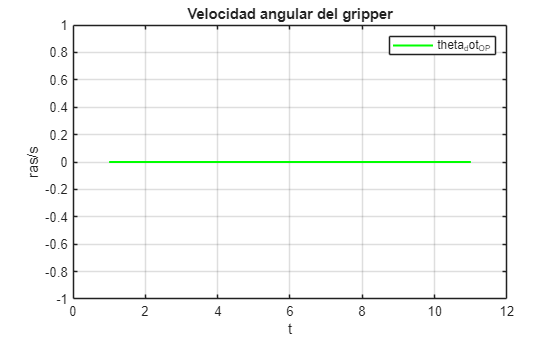


figure 
plot(t_sim, theta_tray_v, 'g-', 'LineWidth', 1.5);
grid on;
xlabel('t'); ylabel('ras/s');
legend('theta_dot_O_P');
title(['Velocidad angular del gripper']);

Velocidades en el espacio de las juntas en el seguiento de trayectorias en el espacio de trabajo

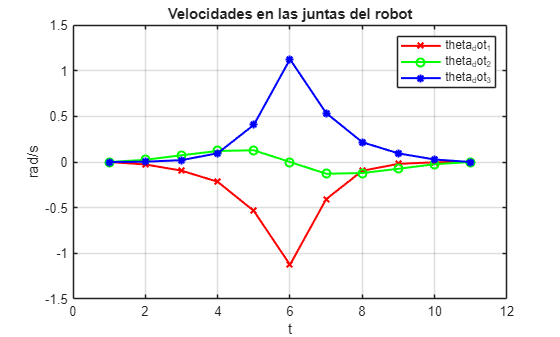


t=0;
for i=1:tf+1
    t = i-1; % Increment time for the next iteration
    % Velocidades en el espacio de las juntas
    x_tray_v(i) =  ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(x_O_P_fin - x_O_P_in);
    y_tray_v(i) = ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(y_O_P_fin - y_O_P_in);
    theta_tray_v(i) =  ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(theta_O_P_fin - theta_O_P_in);
    
    % velocidad de calculada 
    x_dot = x_tray_v(i);
    y_dot = y_tray_v(i);
    theta_dot_P = theta_tray_v(i);

    % postura del robot    
    theta_O_1 = theta_1_tray(i);
    theta_1_2 = theta_2_tray(i);
    theta_2_3 = theta_3_tray(i);

    % calculo de las velicidades de las juntas con base en el Jacobiano
    theta_1_v(i) = (x_dot*cos(theta_1_2 + theta_O_1))/(L1*sin(theta_1_2)) + (y_dot*sin(theta_1_2 + theta_O_1))/(L1*sin(theta_1_2)) + (L3*theta_dot_P*sin(theta_2_3))/(L1*sin(theta_1_2));
    theta_2_v(i) = - (x_dot*(L2*cos(theta_1_2 + theta_O_1) + L1*cos(theta_O_1)))/(L1*L2*sin(theta_1_2)) - (y_dot*(L2*sin(theta_1_2 + theta_O_1) + L1*sin(theta_O_1)))/(L1*L2*sin(theta_1_2)) - (L3*theta_dot_P*(L1*sin(theta_1_2 + theta_2_3) + L2*sin(theta_2_3)))/(L1*L2*sin(theta_1_2));
    theta_3_v(i) = (theta_dot_P*(L3*sin(theta_1_2 + theta_2_3) + L2*sin(theta_1_2)))/(L2*sin(theta_1_2)) + (x_dot*cos(theta_O_1))/(L2*sin(theta_1_2)) + (y_dot*sin(theta_O_1))/(L2*sin(theta_1_2));
    
end

figure
plot(t_sim, theta_1_v, 'r-x', 'LineWidth', 1.5);
hold on;
plot(t_sim, theta_2_v, 'g-o', 'LineWidth', 1.5);
plot(t_sim, theta_3_v, 'b-*', 'LineWidth', 1.5);
grid on;
xlabel('t'); ylabel('rad/s');
legend('theta_dot_1', 'theta_dot_2', 'theta_dot_3');
title(['Velocidades en las juntas del robot']);

Calculo de las velociades en la plación en el espacio de las juntas

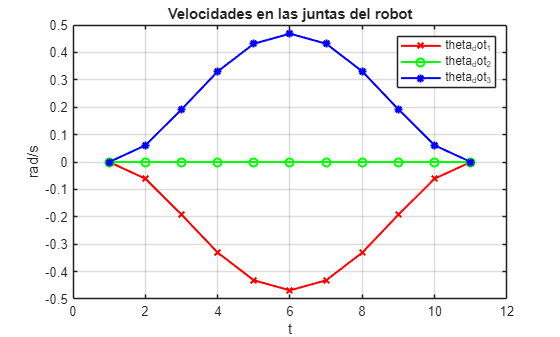

tf = 10;

for i=1:tf+1
    t = i-1; % Increment time for the next iteration
    theta_1_q(i) =  ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(theta_1_q_fin-theta_1_q_in);
    theta_2_q(i) =  ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(theta_2_q_fin-theta_2_q_in);
    theta_3_q(i) =  ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(theta_3_q_fin-theta_3_q_in);
end

figure
plot(t_sim, theta_1_q, 'r-x', 'LineWidth', 1.5);
hold on;
plot(t_sim, theta_2_q, 'g-o', 'LineWidth', 1.5);
plot(t_sim, theta_3_q, 'b-*', 'LineWidth', 1.5);
grid on;
xlabel('t'); ylabel('rad/s');
legend('theta_dot_1', 'theta_dot_2', 'theta_dot_3');
title(['Velocidades en las juntas del robot']);

## Soluciones numericas